% Luke McCubbin 
%Post compensation

clear all;

% Read the CSV file into a table
data = readtable('Xy_test_combined.csv');


% Extract each variable
x_real = data.xI_real;
x_imag = data.xI_imag;
y_real = data.yout_real;
y_imag = data.yout_imag;

% Combine into complex numbers if needed
x_mem_complex = complex(x_real, x_imag);
y_mem_complex = complex(y_real, y_imag);

% Combine into one matrix
%data = [xI_real, xI_imag, yout_real, yout_imag];
%x_mem_complex = x_mem_complex .* 10^(-6/20); % Scale the values
 


% Parameters
npoints=length(x_mem_complex);  % Number of points
chip = 100e6;    % 100 MHz signal bandwidth
Fs = chip * 10;  % Sampling frequency

% Time vector
t = (0:npoints-1)/Fs;

power_avg_input = trapz(t, abs(x_mem_complex).^2) / ((t(end) - t(1))*100);  % Using numerical integration

power_input = 10 * log10(power_avg_input/1e-3);
fprintf('Input data Average Power (dBm): %f dBm\n', power_input)

Input data Average Power (dBm): 1.961539 dBm





%xI_actual = xI_predict.*10^(10/20);

figure(137)
spec_plot(y_mem_complex,1/Fs,135,'predicted output');

acpr value: -0.01 dB


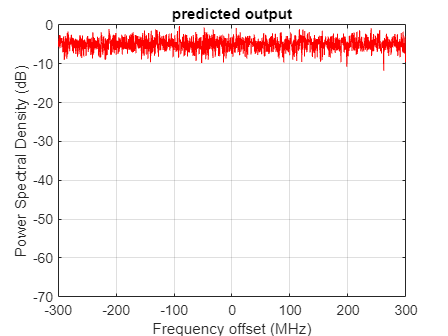

axis([-300 300 -70 0])


figure(138)
spec_plot(x_mem_complex,1/Fs,135,'ideal input');

acpr value: -0.05 dB


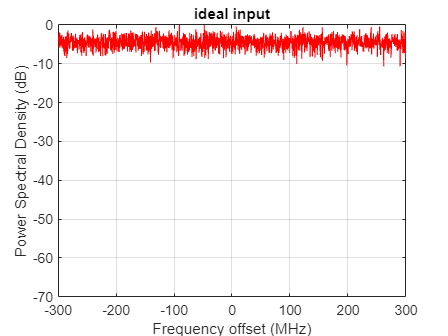

axis([-300 300 -70 0])



% power_avg_input = trapz(t, abs(xI_predict).^2) / ((t(end) - t(1))*100);  % Using numerical integration
% 
% power_input = 10 * log10(power_avg_input/1e-3);
% fprintf('Predicted data Average Power (dBm): %f dBm\n', power_input);
% 
% figure(137)
% [P_spec_input, F_spec_input] =spec_plot(x_mem_complex,1/Fs,135,'Input');
% axis([-300 300 -100 0])
% figure(1351)
% pwelch(x_mem_complex,[],[],[],Fs)      %%% spectrum of output
% xlim([0 0.8])
% 
% disp(sprintf('Baseband Input Peak-to-average ratio: %1.2f dB', 20*log10(max(abs(x_mem_complex))/rms(abs(x_mem_complex)))));
% 
% PoutpkW=max(abs(x_mem_complex))^2/2/50;     %% peak output power in W
% InputPoutpkdBm=10*log10(PoutpkW)+30     %%% peak output power in dBm
% 
% npoints2 = length(x_mem_complex);
% 
% t2 = (0:npoints2-1)/Fs;
% 
% power_avg_input = trapz(t2, abs(x_mem_complex).^2) / ((t2(end) - t2(1))*100);  % Using numerical integration
% 
% power_input = 10 * log10(power_avg_input/1e-3);
% fprintf('Matlab input data Average Power (dBm): %f dBm\n', power_input);
% 
% figure(137)
% [P_spec_output, F_spec_output] = spec_plot(y_mem_complex,1/Fs,135,'Output');
% axis([-300 300 -100 0])
% figure(1351)
% pwelch(y_mem_complex,[],[],[],Fs)      %%% spectrum of output
% xlim([0 0.8])
% 
% disp(sprintf('Baseband Matlab output Peak-to-average ratio: %1.2f dB', 20*log10(max(abs(y_mem_complex))/rms(abs(y_mem_complex)))));
% 
% PoutpkW=max(abs(y_mem_complex))^2/2/50;     %% peak output power in W
% OutputPoutpkdBm=10*log10(PoutpkW)+30     %%% peak output power in dBm
% 
% npoints2 = length(y_mem_complex);
% 
% t2 = (0:npoints2-1)/Fs;
% 
% power_avg_input = trapz(t2, abs(y_mem_complex).^2) / ((t2(end) - t2(1))*100);  % Using numerical integration
% 
% power_input = 10 * log10(power_avg_input/1e-3);
% fprintf('Matlab output data Average Power (dBm): %f dBm\n', power_input);
% 
% N = length(xI_predict);
% 
% [pxx, f] = pwelch(xI_predict, hamming(1024), [], [], Fs, 'centered');
% 

% % Plot
% figure;
% plot(F_spec_input, P_spec_input, 'r-', 'LineWidth', 2); % First line in red
% hold on;
% plot(F_spec_output, P_spec_output, 'b-', 'LineWidth', 2); % Second line in blue dashed
% plot(F_spec_predicted, P_spec_predicted, 'g-', 'LineWidth', 2); % Second line in blue dashed
% hold off;
% 
% % Labels and Title
% xlabel('Freq');
% ylabel('Power');
% title('Spectrum Plot');
% legend('Ideal', 'Distorted', 'NN compensated');
% grid on;



% % Define time range
% t_start = 0;           % Start time in seconds
% t_end = 30e-6;         % End time in seconds (30 microseconds)
% 
% % Generate linearly spaced time vector
% time = linspace(t_start, t_end, 30000);
% 
% % Display basic info
% disp(['Time vector size: ', num2str(size(time))]);
% disp(['First time value: ', num2str(time(1)), ' s']);
% disp(['Last time value: ', num2str(time(end)), ' s']);
% 
% 
% 
% save('Sim10dbmVinVout.mat', 'time', 'xI_predict7dB', 'output_dist_7dB', 'output_predist_7dB', 'post_predict10dB', 'output_dist_10dB')